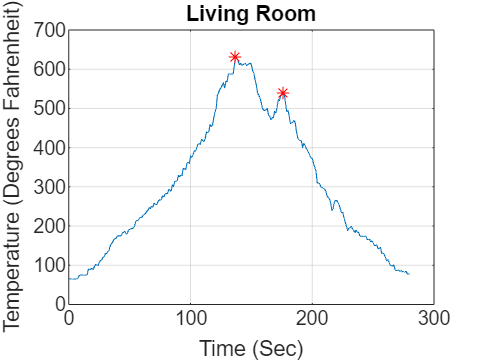

filename = 'firedata.xlsx';

% Read the data from the Excel file
data = xlsread(filename);

% Extract the x and y values
x = data(:, 1);  % Assuming x-values are in the first column
y = data(:, 2);  % Assuming y-values are in the second column

% Plot the data
plot(x, y, '-');  % Plot with lines connecting points
xlabel('Time (Sec)');
ylabel('Temperature (Degrees Fahrenheit)');
title('Living Room');
grid on;  % Show grid

% Find local maxima with specified minimum prominence
minProminence = 20;
TF = islocalmax(y, 'MinProminence', minProminence);

% Filter out local maxima that are not separated by at least 15 seconds
minSeparation = 45;  % in seconds
minSeparationIndex = find(diff(x) >= minSeparation);
if ~isempty(minSeparationIndex)
    TF = TF & [false; diff(x(TF)) >= minSeparation];
end

% Filter out local maxima that are below 400 degrees
TF = TF & y > 400;

% Plot the identified maxima
hold on;
plot(x(TF), y(TF), 'r*');
hold off;


% Find the maximum value among the identified maxima
maxValueY = max(y(TF));

disp(['Maximum value in identified maxima: ', num2str(maxValueY)]);

Maximum value in identified maxima: 632



% List all the local maxima
disp('Local Maxima:');

Local Maxima:


disp(['x', 'y']);

xy


disp([x(TF), y(TF)]);

   137   632
   176   540

